clear variables

fname = 'Job-3-1kg-size10.inp';
[Nodes, Elements] = Readmesh(fname);
NodeCount = size(Nodes,1) ;     % 节点个数
ElementCount= size(Elements,1); % 单元个数
ElementNodeCount=8;             % 每个单元节点数

load Project_1_ForceIdentification\Data\experimentAIPlate\7075Al_size10_0714.mat

K = globalStiffness;
M = globalMass;

M_Shell = diag(sum(M));

[dimx,dimy] = find(K>10e30);
K_Shell = K;

K_Shell(sub2ind(size(K_Shell),dimx,dimy)) = K(sub2ind(size(K),dimx,dimy))*10e-29;

Dof = 3;
Forces = [26 2;42 2;15 2;];
ConDOF = Dof*(Forces(:,1)-1)+Forces(:,2);       % 计算外力自由度编号
Obs = [22 2;3 2;45 2;46 2;40 2;39 2];
ObsDOF = Dof*(Obs(:,1)-1)+Obs(:,2);             % 计算控制点自由度编号

opt = [];

inputDim = size(ConDOF,1);
outputDim = size(ObsDOF,1);
opt.damp.alpha = 0.004;
opt.damp.belta = 0.001;

dim = size(M_Shell,1);
inputsize = size(ConDOF,1);
outputsize = size(ObsDOF,1);

DD = zeros(dim,inputsize);

for i = 1:inputsize
    DD(ConDOF(i,:),i) = 1;
end

C = zeros(outputsize,dim);
for i = 1:outputsize
    C(i,ObsDOF(i,:)) = 1;
end

D = 0.004*K_Shell+0.001*M_Shell;

sys = second2first(M_Shell,D,K_Shell,DD,C);

opts = [];
opts.Order = {6,7,8,9,10};
opts.OrderComputation = 'order';
opts.FreqRange = [0,100];
[sysflbt,info] = ml_ct_dss_flbt(ss(sys),opts);

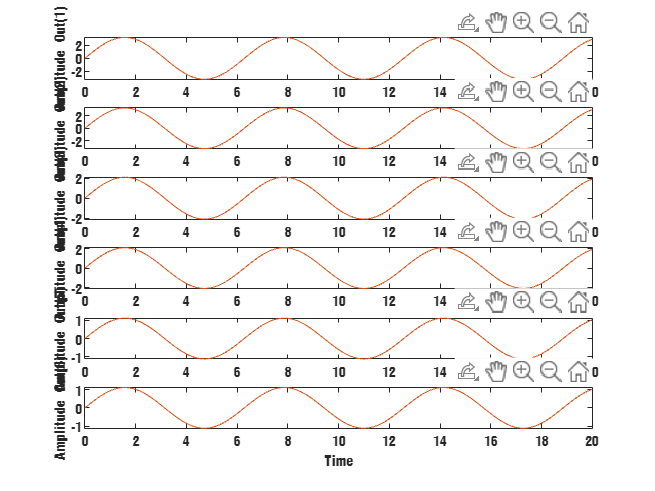

figure;
u = @(t) sin(t) * ones(3, 1);
opts = [];
opts = struct('InputFcn', u, 'TimeRange', 20);
ml_ct_dss_simulate_ie(sysflbt{1},opts);

sysDis = c2d(ss(sys),0.05);

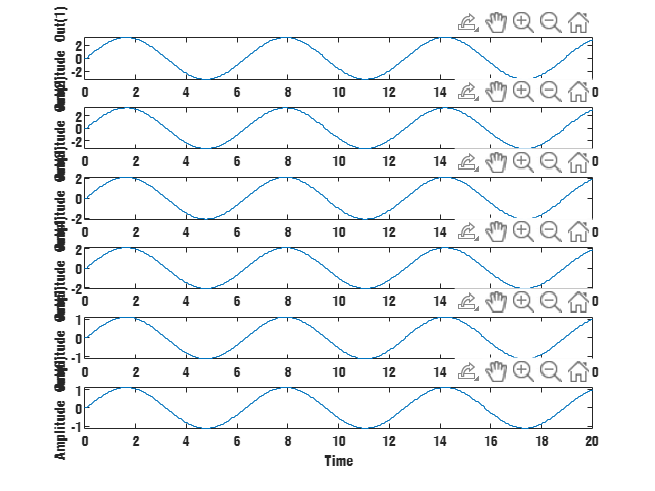

figure;
u = @(t) sin(t) * ones(3, 1);
opts = [];
opts = struct('InputFcn', u, 'TimeRange', 20);
ml_dt_ss_simulate(sysDis,opts);

sysDisFoh = c2d(ss(sys),0.05,'foh');

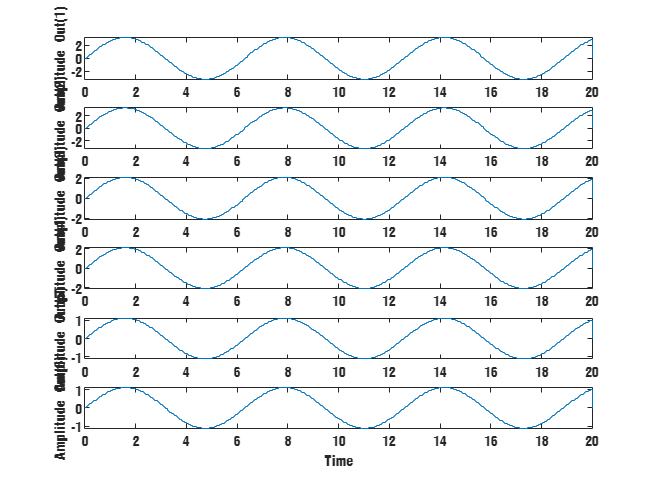

figure;
u = @(t) sin(t) * ones(3, 1);
opts = [];
opts = struct('InputFcn', u, 'TimeRange', 20);
ml_dt_ss_simulate(sysDisFoh,opts);

[A,B,C,D,E] = dssdata(ss(sys));
sysSparss = sparss(A,B,C,D,E);
sysDisSparss = c2d(sysSparss,0.05,'tustin');

错误使用 DynamicSystem/c2d
For sparse models, the "c2d" method must be 'tustin' or 'damped'.

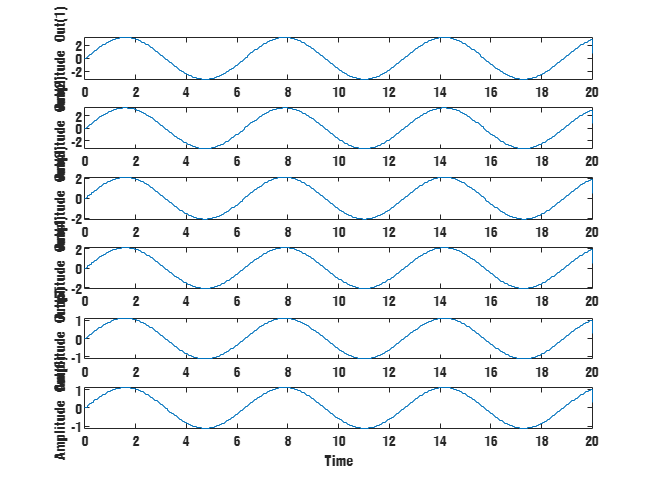

figure;
u = @(t) sin(t) * ones(3, 1);
opts = [];
opts = struct('InputFcn', u, 'TimeRange', 20);
ml_dt_dss_simulate(full(sysDisSparss),opts);

sysDisSSS = c2d(sys,0.05);

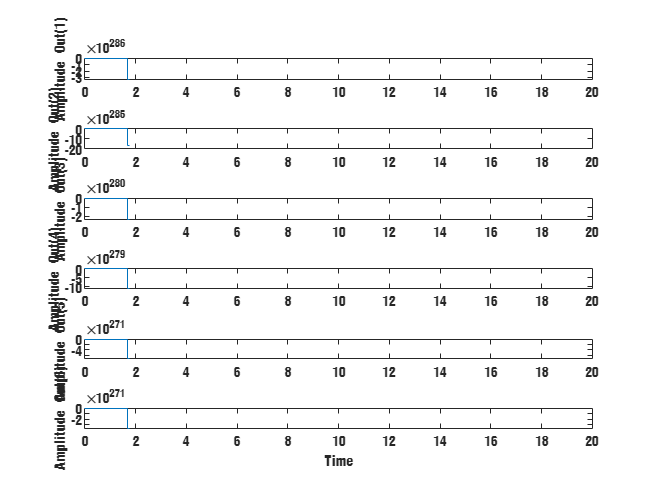

figure;
u = @(t) sin(t) * ones(3, 1);
opts = [];
opts = struct('InputFcn', u, 'TimeRange', 20);
ml_dt_dss_simulate(ss(sysDisSSS),opts);

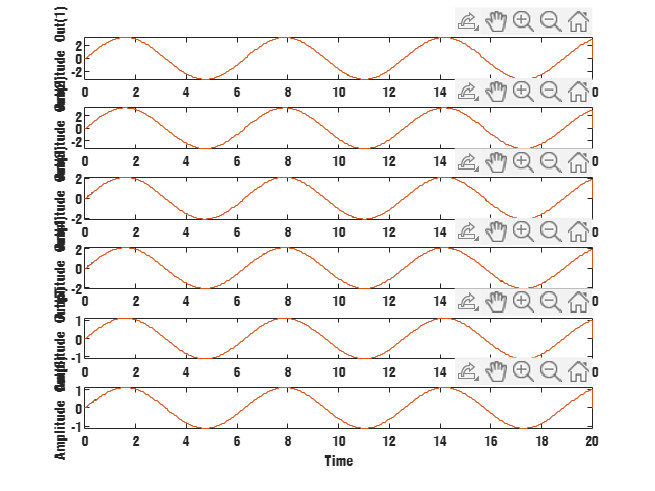

figure;
u = @(t) sin(t) * ones(3, 1);
opts = [];
opts = struct('InputFcn', u, 'TimeRange', 20);
ml_dt_dss_simulate(full(sysDisSparss),opts);
hold on 
ml_dt_ss_simulate(sysDisFoh,opts);

% 使用这两种方法离散化没啥区别
